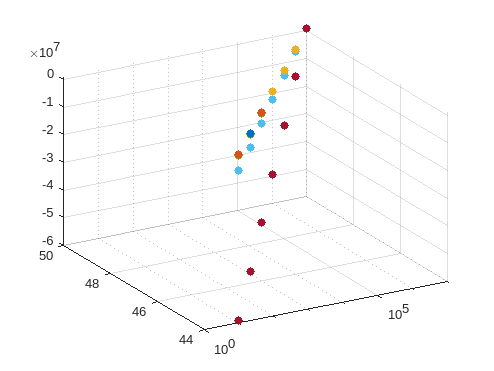

clearvars;

% wykres 3d - gameCount / winRate / balance

gameCount = zeros(7,1); % X
winRate = zeros(1,7);   % Y
balance = zeros(7,7);   % Z
count = 10;
wr = 44;
start = 1000000;

for i = 1:7
    
    gameCount(i,1) = count;
    count = count * 10;

    winRate(1,i) = wr;
    wr = wr + 1;

end

for count = 1:7
    for rate = 1:7
        balance(rate, count) = start - 1*(50-winRate(rate))*gameCount(count);
    end
end

scatter3(gameCount,winRate,balance,'filled')
set(gca,'XScale','log')
view(-30,30)